# IET-GPR documentation

## Example 3

Migrate data from a GSSI-StructureScan Mini GPR.

### Start the IET-GPR software and load a GPR file

See Example 1 for details of this section.

clear
run('..\ietgpr')
filename = 'data\File____002.dzt';
[data, dataHeader] = readdzt(filename);

### Remove the linear offset and apply a gain function

See Example 2 for details of this section.

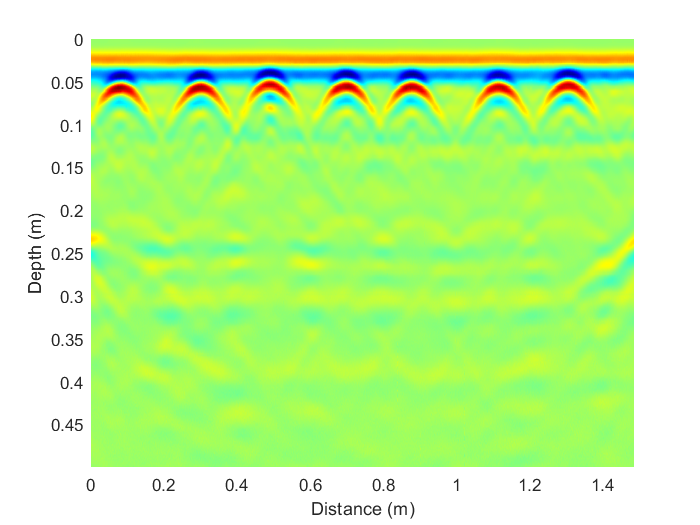

pdata = linearoffset(data);
pdata = iadgain1(pdata, 0.75);
plotbscan(pdata, dataHeader, 9);

### Reduce the amount of data

Resize (**resizescan** function) or trim (**trimscan** function) the data to reduce the computational complexity of the SAFT algotithm.

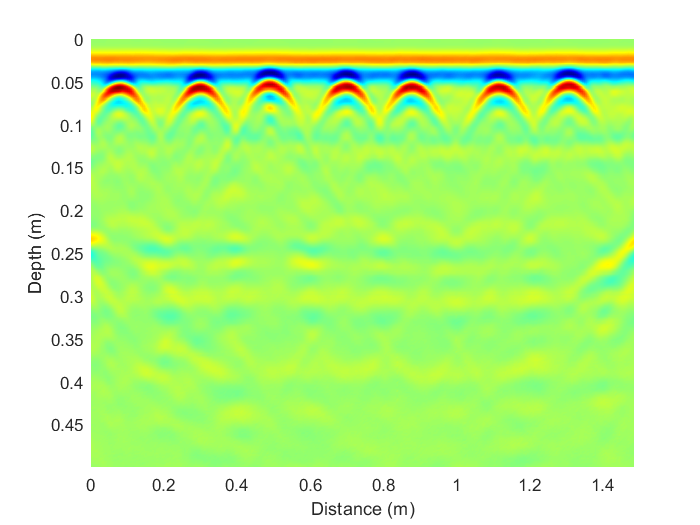

[pdata, pdataHeader] = resizescan(pdata, dataHeader, round(dataHeader.numOfColumns/4));
plotbscan(pdata, pdataHeader, 9);

### Apply the SAFT migration algorithm

Apply the synthetic aperture focusing technique (SAFT) process to the data and plot the result.

tic
[saft, saftHeader] = saftproc(pdata, pdataHeader, 9);
toc

Elapsed time is 0.846629 seconds.


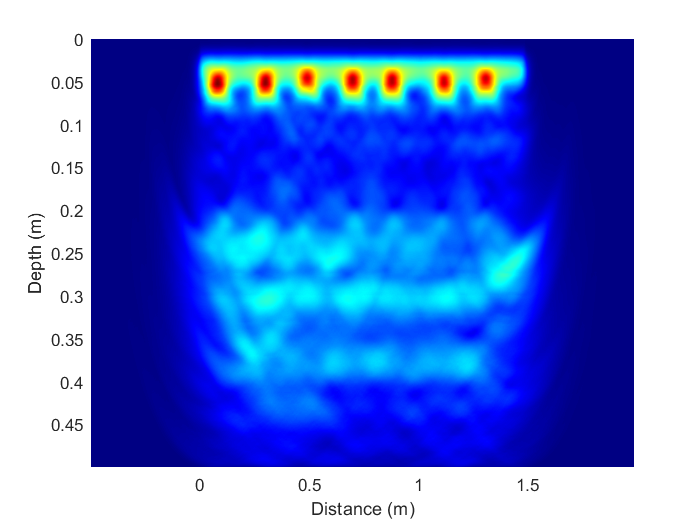

plotbscan(saft, saftHeader, 9);

Optionally, it is possible to use the **saftpost** function for trim or mirror the edges of the SAFT data.

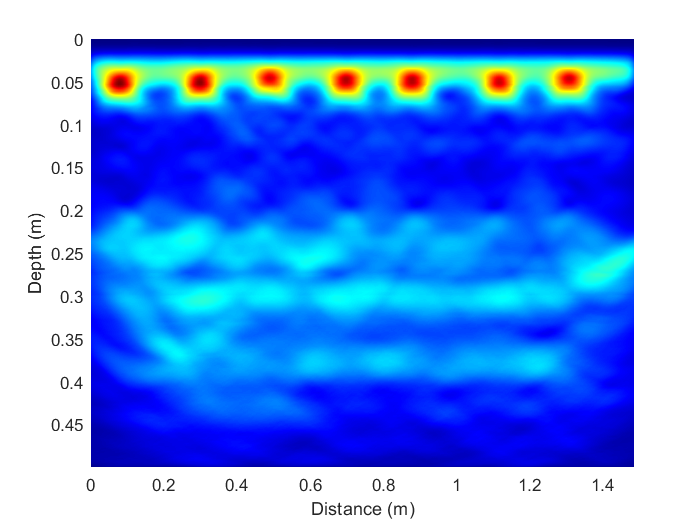

[saft, saftHeader] = saftpost(saft, saftHeader);
plotbscan(saft, saftHeader, 9);